# **PESTools - Example 007 - Showcase of the available ARPES model curves that can be used for fitting**

## PCC

This example shows all of the curve line-shapes that are available to use when fitting to either ARPES or XPS data obtained from the ADRESS beamline. 

- **For ARPES curves:** **2D** **Gaussian**, **2D** **Lorentzian**, **2D** **Voigt** functions are available.

- The **Fermi-Dirac Distribution** **(FDD)** is also used if necessary for fitting states near the Fermi-edge.

- Using the 2D model curves, band dispersions can be plotted and compared to data.

close all; clear all;
pp = plot_props();

# **Symmetric Curves**

xdat = linspace(-3, 3, 1e2);
ydat = linspace(-3, 3, 1e2);

## (1) Gaussian 2D Lineshape

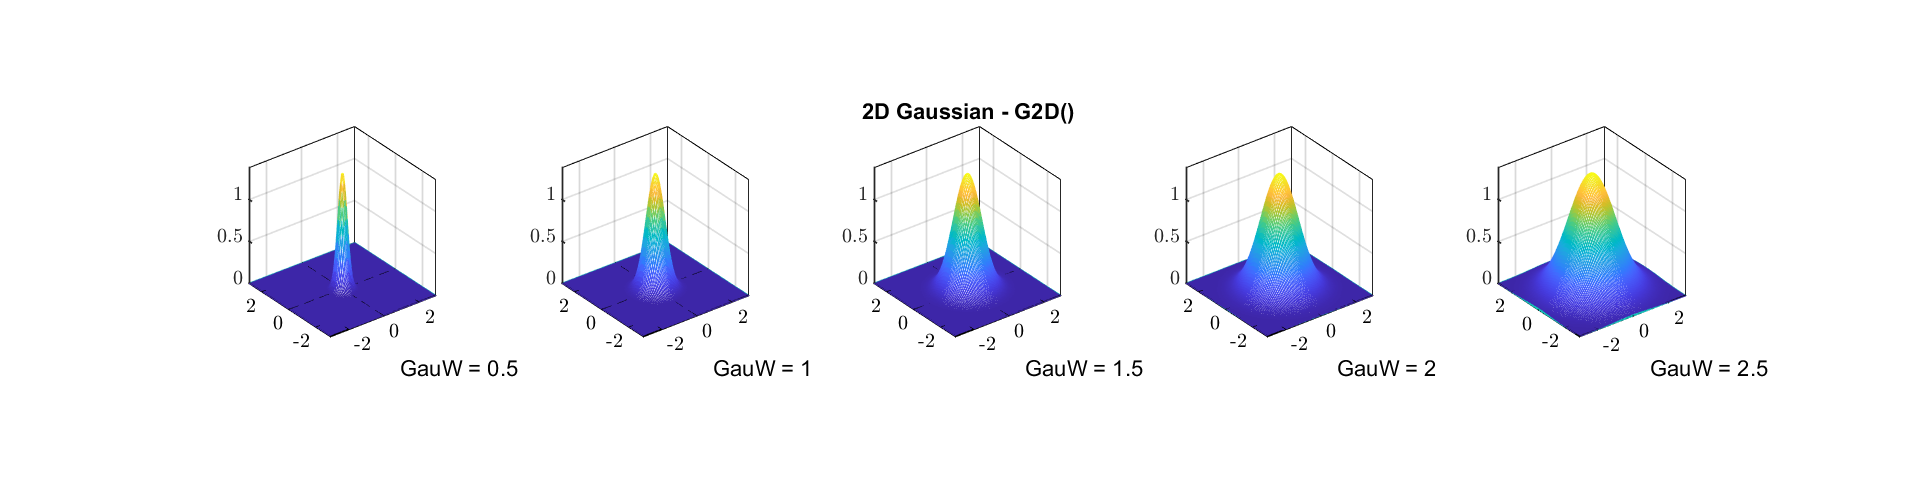

% 1 - Defining the input parameters
peak        = 1.38;         % scalar of the peak beneath the Gaussian.
x0          = 0;            % scalar of the peak position along the x-axis of the Gaussian.
y0          = 0;            % scalar of the peak position along the x-axis of the Gaussian.
fwhm       = 0.5:0.5:2.5;   % scalar of the full-width at half-maximum (FWHM) of the Gaussian.
% 2 - Calculating the 2D lineshape
lgnd = {};
for i = 1:length(fwhm)
    int_gauss{i}    = G2D(xdat, ydat, peak, x0, y0, fwhm(i));
    lgnd{i}         = "GauW = " + string(fwhm(i));
end
% 3 - Plotting the lineshapes & verifying the FWHM values
fig = figure(); 
fig.Position(3) = 4.*pp.fig4x4(1);
fig.Position(4) = 1.*pp.fig4x4(2);
for i = 1:length(fwhm)
    subplot(1,length(fwhm),i)
    meshz(xdat, ydat, int_gauss{i});
    gca_props(); axis square;
    xlabel(lgnd{i}); 
    if i == 3; title('2D Gaussian - G2D()'); end
end

## (2) Lorentzian 2D Lineshape

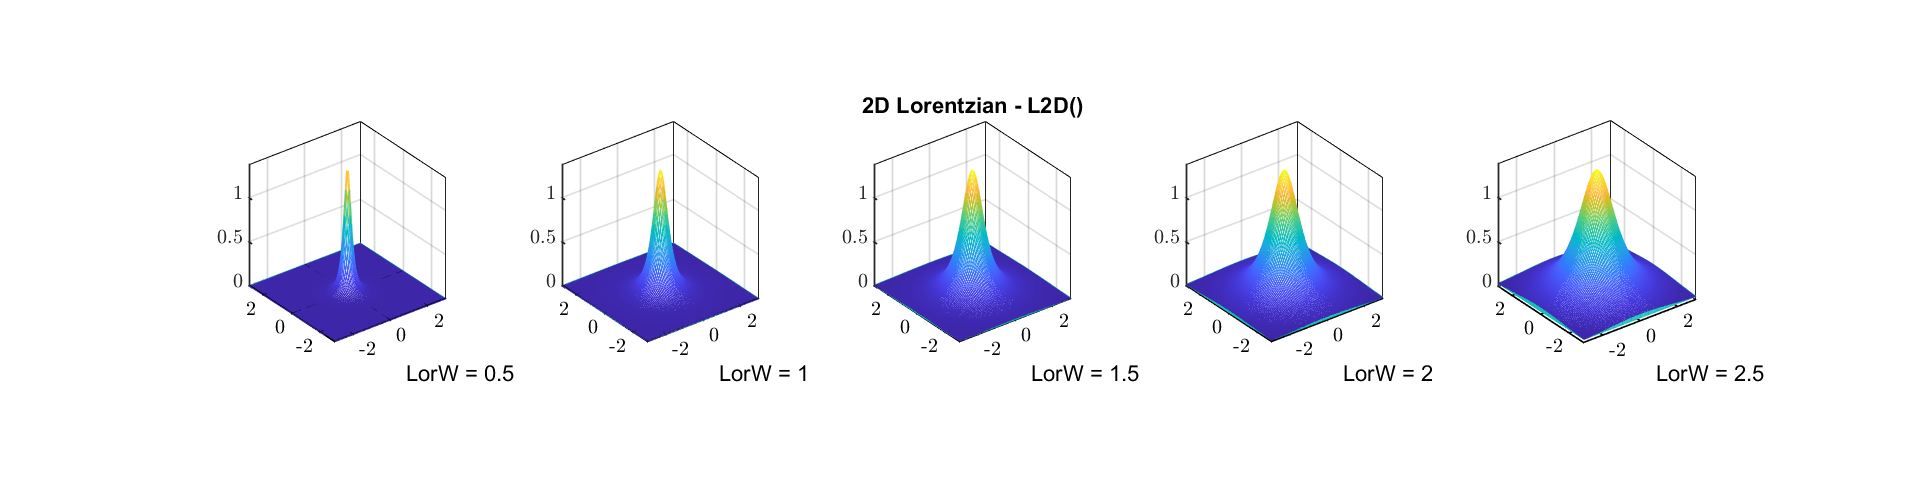

% 1 - Defining the input parameters
peak        = 1.38;         % scalar of the peak beneath the Gaussian.
x0          = 0;            % scalar of the peak position along the x-axis of the Gaussian.
y0          = 0;            % scalar of the peak position along the x-axis of the Gaussian.
fwhm       = 0.5:0.5:2.5;   % scalar of the full-width at half-maximum (FWHM) of the Gaussian.
% 2 - Calculating the 2D lineshape
lgnd = {};
for i = 1:length(fwhm)
    int_lorz{i}    = L2D(xdat, ydat, peak, x0, y0, fwhm(i));
    lgnd{i}         = "LorW = " + string(fwhm(i));
end
% 3 - Plotting the lineshapes & verifying the FWHM values
fig = figure(); 
fig.Position(3) = 4.*pp.fig4x4(1);
fig.Position(4) = 1.*pp.fig4x4(2);
for i = 1:length(fwhm)
    subplot(1,length(fwhm),i)
    meshz(xdat, ydat, int_lorz{i});
    gca_props(); axis square;
    xlabel(lgnd{i}); 
    if i == 3; title('2D Lorentzian - L2D()'); end
end

# **Asymmetric Curves**

xdat = linspace(-3, 3, 1e2);
ydat = linspace(-3, 3, 1e2);

## (1) Gaussian 2D Lineshape

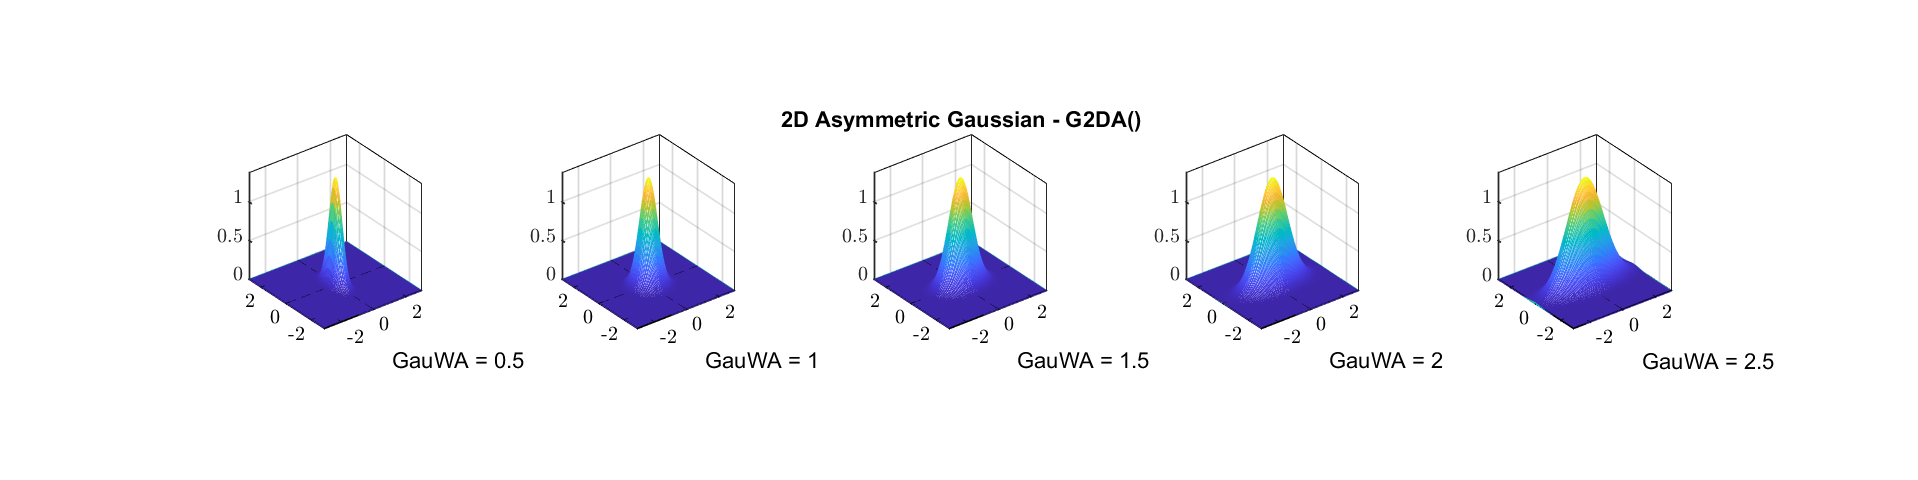

% 1 - Defining the input parameters
peak        = 1.38;         % scalar of the peak beneath the Gaussian.
x0          = 0;            % scalar of the peak position along the x-axis of the Gaussian.
y0          = 0;            % scalar of the peak position along the x-axis of the Gaussian.
xfwhm       = 0.5:0.5:2.5;  % scalar of the full-width at half-maximum (FWHM) of the Gaussian.
yfwhm       = 1;            % scalar of the full-width at half-maximum (FWHM) of the Gaussian.
% 2 - Calculating the 2D lineshape
lgnd = {};
for i = 1:length(xfwhm)
    int_gauss{i}    = G2DA(xdat, ydat, peak, x0, y0, xfwhm(i), yfwhm);
    lgnd{i}         = "GauWA = " + string(xfwhm(i));
end
% 3 - Plotting the lineshapes & verifying the FWHM values
fig = figure(); 
fig.Position(3) = 4.*pp.fig4x4(1);
fig.Position(4) = 1.*pp.fig4x4(2);
for i = 1:length(xfwhm)
    subplot(1,length(xfwhm),i)
    meshz(xdat, ydat, int_gauss{i});
    gca_props(); axis square;
    xlabel(lgnd{i}); 
    if i == 3; title('2D Asymmetric Gaussian - G2DA()'); end
end

# **Angle-Resolved Curves**

The function 'ARPESCurve()' can be used to call any 2D curve line-shape that is plotted with a particular effective mass and energy.

Using a linear combination of 'ARPESCurve()' outputs, we can then fit to any ARPES band dispersions.

## (1) Generic ARPES Curve

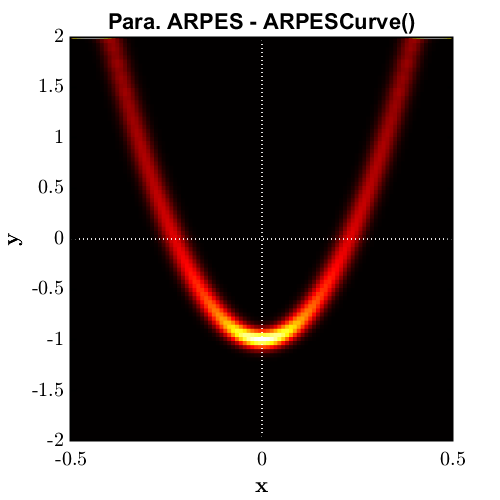

% 1 - Defining the input parameters
xdat = linspace(-0.5, 0.5, 1e2);    % 1xM row vector of the x-axis domain
ydat = linspace(-2, 2, 1e2);        % Nx1 column vector of the y-axis domain
cTYPE   = "G2DA";       % type of curve to use for fitting. Default: "G2DA" ("G2D", "L2D")
INT     = 1.0;          % scalar of the peak intensity of 2D PE curve.
XLOC    = 0.00;         % scalar of the x-location of the min/max of the 2D parabolic ARPES dispersion.
YLOC    = -1.00;        % scalar of the y-location of the min/max of the 2D parabolic ARPES dispersion.
XFWHM   = 0.05;         % scalar of the x-axis FWHM for each Gaussian (k-resolution)
YFWHM   = 0.15;         % scalar of the y-axis FWHM for each Gaussian (Eb-resolution)
MSTAR   = 0.20;         % scalar of the effective mass, which governs the curvature of the parabola.
% 2 - Calculating the lineshape
zdat    = ARPESCurve(xdat, ydat, cTYPE, INT, XLOC, YLOC, XFWHM, YFWHM, MSTAR);
% 3 - Plotting the lineshapes & verifying the FWHM values
fig = figure(); fig.Position(3) = pp.fig4x4(1); fig.Position(4) = pp.fig4x4(2);
hold on;
ImData(xdat, ydat, zdat);
img_props(); 
xlabel('$$ \bf  x $$', 'Interpreter', 'latex');
ylabel('$$ \bf  y $$', 'Interpreter', 'latex');
title('Para. ARPES - ARPESCurve()', 'Interpreter', 'none');
axis([min(xdat(:)), max(xdat(:)), min(ydat(:)), max(ydat(:))]);

## (2) Generic ARPES Curve with FDD Convolution

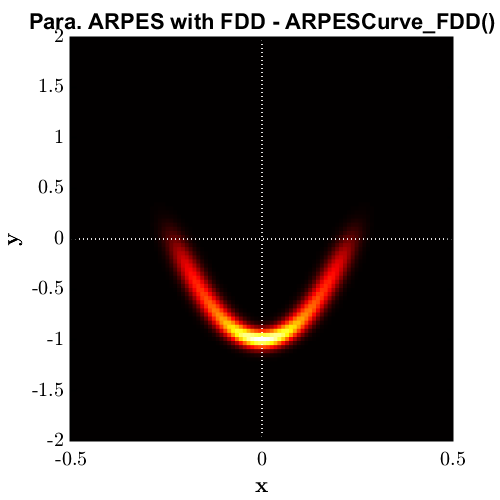

% 1 - Defining the input parameters
xdat = linspace(-0.5, 0.5, 1e2);    % 1xM row vector of the x-axis domain
ydat = linspace(-2, 2, 1e2);        % Nx1 column vector of the y-axis domain
cTYPE   = "G2DA";       % type of curve to use for fitting. Default: "G2DA" ("G2D", "L2D")
INT     = 1.0;          % scalar of the peak intensity of 2D PE curve.
XLOC    = 0.00;         % scalar of the x-location of the min/max of the 2D parabolic ARPES dispersion.
YLOC    = -1.00;        % scalar of the y-location of the min/max of the 2D parabolic ARPES dispersion.
XFWHM   = 0.05;         % scalar of the x-axis FWHM for each Gaussian (k-resolution)
YFWHM   = 0.15;         % scalar of the y-axis FWHM for each Gaussian (Eb-resolution)
MSTAR   = 0.20;         % scalar of the effective mass, which governs the curvature of the parabola.
FDEF    =  0.00;         % scalar of the FDD Fermi-Level position.
FDT     =  12.0;        % scalar of the FDD temperature.
FDW     =  0.10;        % scalar of the FDD Gaussian width after convolution.
% 2 - Calculating the lineshape
zdat    = ARPESCurve_FDD(xdat, ydat, cTYPE, INT, XLOC, YLOC, XFWHM, YFWHM, MSTAR, FDEF, FDT, FDW);
% 3 - Plotting the lineshapes & verifying the FWHM values
fig = figure(); fig.Position(3) = pp.fig4x4(1); fig.Position(4) = pp.fig4x4(2);
hold on;
ImData(xdat, ydat, zdat);
img_props();
xlabel('$$ \bf  x $$', 'Interpreter', 'latex');
ylabel('$$ \bf  y $$', 'Interpreter', 'latex');
title('Para. ARPES with FDD - ARPESCurve_FDD()', 'Interpreter', 'none');
axis([min(xdat(:)), max(xdat(:)), min(ydat(:)), max(ydat(:))]);